Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 2 -- Heart Rate Variance

%% ME 5714 -- Assignment 2
%{
    This live script will be used to complete the assigned work for ME 5714
    assignment 2. This script will be used to calculate the variance of
    heart rate data from two data sets.
    
    Sam Kramer
    21st Jan, 2023
%}

% --Setup
    clear; clc; format compact; close all;

    Heart rate data collected from a sensor designed to monitor blood oxygen levels and heart rate can be used to estimate the probability of Sepsis in pediatric patients. We are only interested in the pulse measurement that is collected. Normally, heart rate data is estimated by counting the number of pulses over a fixed period of time, for example 72 BPM which is the human average. The variance of the pulse rate is known as the heart rate variability or HRV, and is the metric best used for detecting Sepsis in patients.

This MATLAB live script will be used to estimate the HRV from different heart rate data sets.

## Heart Rate Data Figures

    In order to properly process the data, the data should first be displayed and shown. The code below does that displaying the data from Human 1 and Human 2 in a subplot. The x-axis is time in minutes. I will be assuming that in the data, the peaks indicate the heart's pulses. 

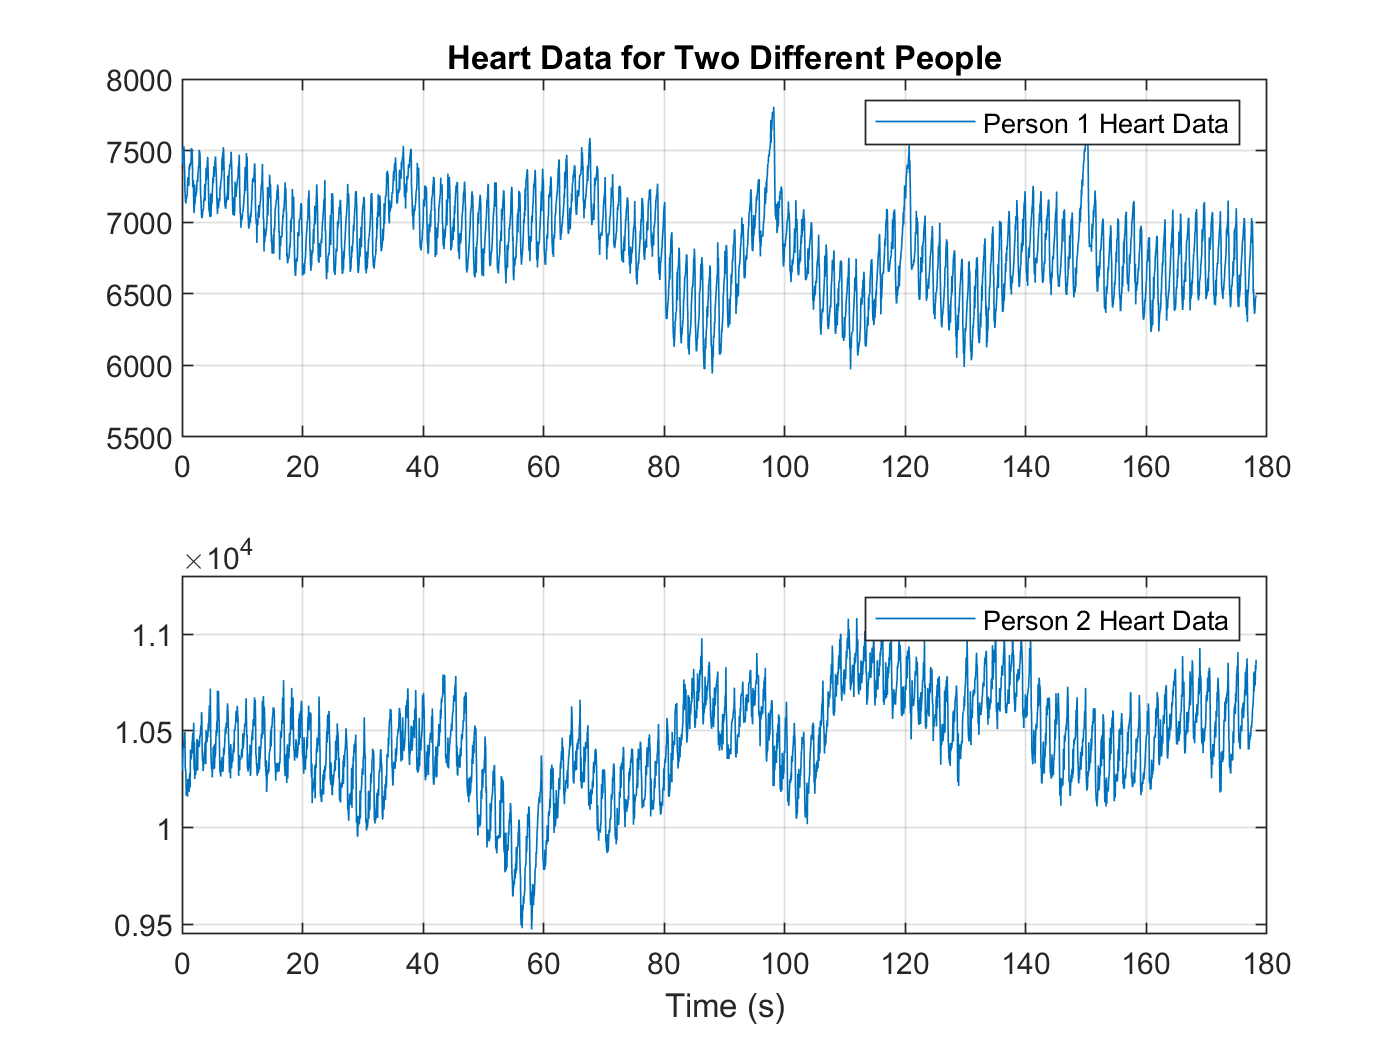

% --Load in data
    person11 = load('human11-1.mat');
    person12 = load('human21.mat');
    
% --Format Data Structs
    pulsePerson1 = person11.human1;
    pulsePerson2 = person12.human2;
    time = person11.t;
    time = time*60;
    
% --Plot Data
    figure1 = figure(1);
    subplot(2,1,1)
    plot(time, pulsePerson1)
        hold on
        title('Heart Data for Two Different People')
        legend('Person 1 Heart Data')
        grid on

    subplot(2,1,2)
    plot(time,pulsePerson2)
        hold on
        xlabel('Time (s)')
        ylim([9450 11300])
        legend('Person 2 Heart Data')
        grid on

## HRV Analysis

    Heart Rate Variation describes the variance in the time difference of the peaks of the heart beat. The higher the HRV is, the more associated it is with good health. Conversely, low HRVs are associated with poor health. The HRV of a data set can be determined in multiple different ways, the time domain, the frequency domain, and with poincare diagrams. For this method I will be using frequency analysis of the data becuase it is impractical to count the peaks and determine the variation in time between them throughout the whole data sample. This is called the Root Mean Squared of Successive Differences Method. Frequency methods can show the variance of the original data set by looking at the area under the curve of the frequency-power diagram. 

    Frequency domain methods rely on the FFT of the data to be performed. The frequency of the data is often looked at in three different regions: High Frequency (HF) which denotes the 0.15 to 0.45 Hz, Low-Frequency Power (LF) which is 0.04 to 0.15 Hz, and Very Low-Power Frequencies (VLF) are also used. For accurate measurements, 2 minutes of data must be taken to have confidence in LF values, and then 5 minutes must be taken to have confidence in VLF values. HF values can be reliably taken with 60 seconds of data. The data that is given only has about 3 minutes of data so any values of the VLF region are unreliable. The frequency is not an actual reading of the heart rate, but a value of the modulation of the heart rate. 

    First, filtering some of the noise from the data will be useful in cleaning up the signal and provide better and more reliable frequency domain readings. To do this a simple low pass filter will be implemented for the data. I assume that it is okay to filter the data because it is not the magnitude of the peaks that is of interest it is the time between the peaks that we are looking at. 

### Person 1:

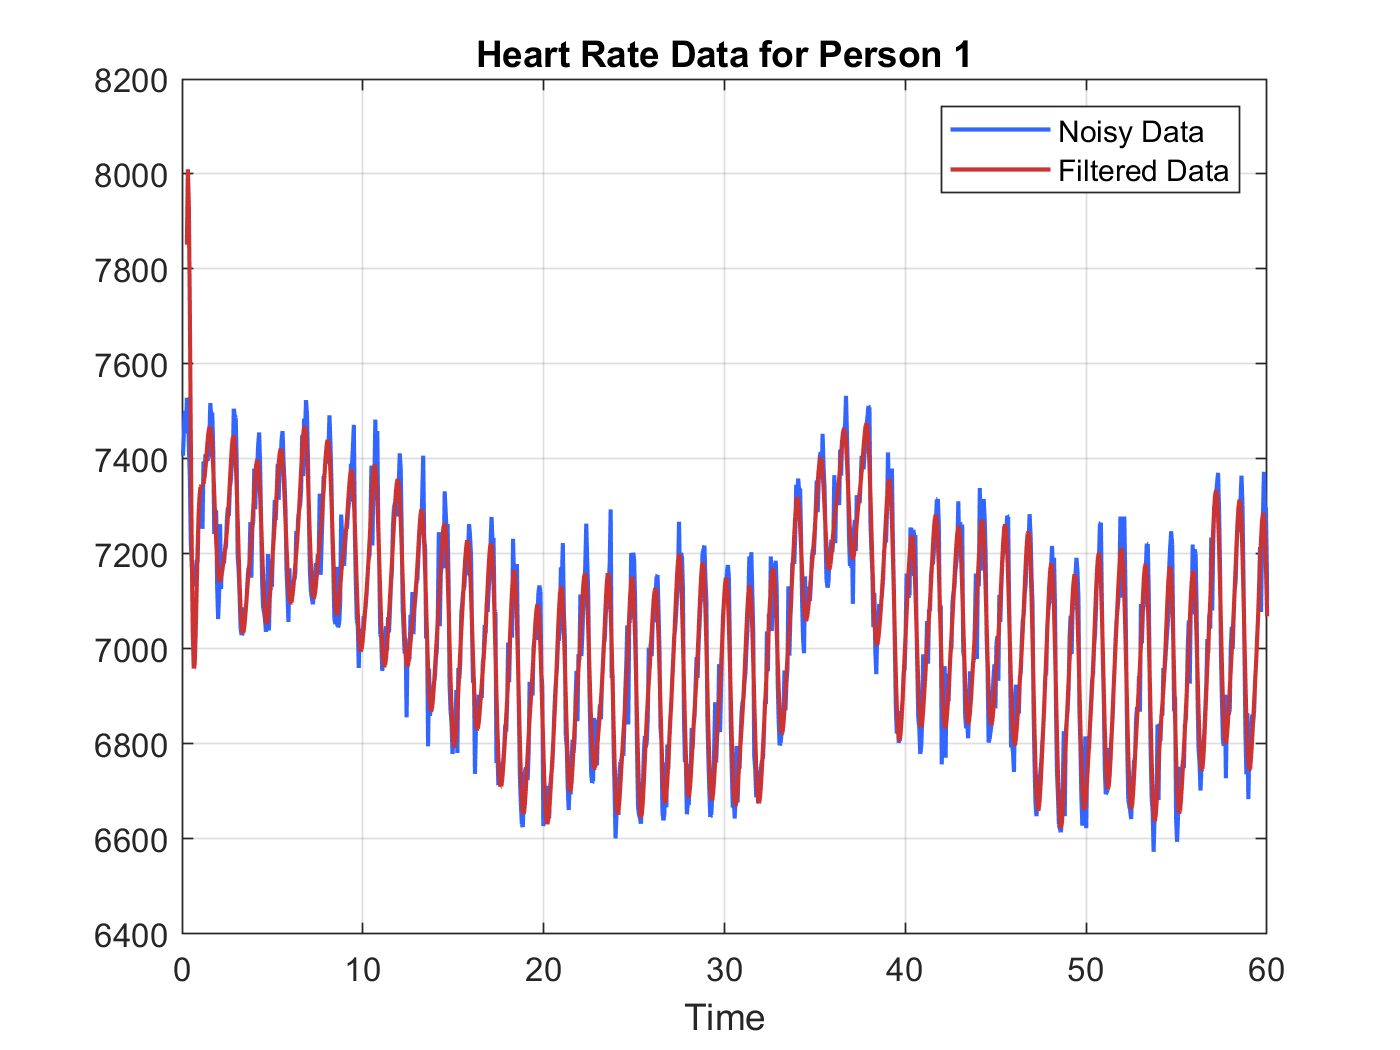

% --Isolate person 1 data
    figure2 = figure(2);
    plot(time,pulsePerson1,'Color',[0.2 0.4 1],'LineWidth',1.25)
        hold on
        xlim([0 60])
        xlabel('Time')
        title('Heart Rate Data for Person 1')

% --Filter ECG signal for Person 1
    filteredPulse1 = lowpass(pulsePerson1,0.1);
    filteredPulse1 = filteredPulse1(5:length(filteredPulse1)-2);
    filteredTime = time(5:length(time)-2);
    plot(filteredTime,filteredPulse1,'Color',[0.8 0.2 0.2],'LineWidth',1.25);
        legend('Noisy Data','Filtered Data')
        grid on

    After the data is filtered, we can then take the FFT of the data to determine the frequency response of the data. The magnitude of the data will be described in the Power Spectral Density or PSD. PSD in general is the frequency distribution of the signal variance. 

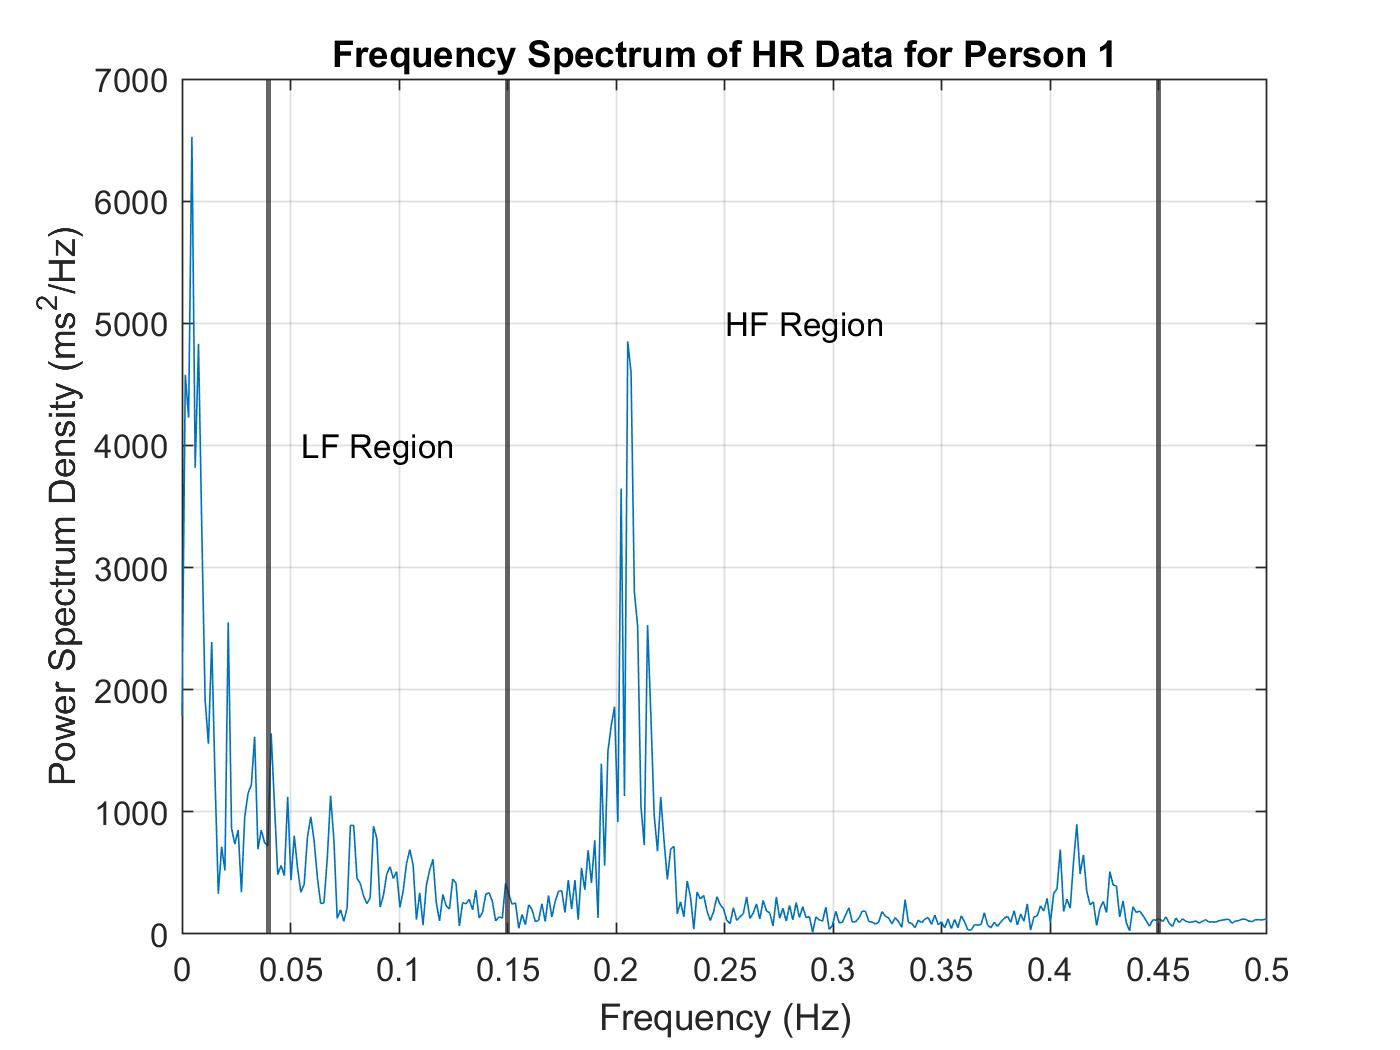

% --FFT of person 1 data
    signalLength = length(filteredPulse1);                      % Signal length
    sample_period = time(2) - time(1);
    sample_frequency = 1/sample_period;
    
    powerPerson1 = fft(filteredPulse1);
    powerPerson1 = powerPerson1(4:(signalLength/2));
    PSD1 = (abs(powerPerson1))/(2*sample_frequency);            % Power spectral density of person 1 data
    
% --Calculating frequency
    frequency = linspace(0,2.5,length(PSD1));                   % Frequency Spectrum                 
    
% --Plotting FFT diagram
    figure();
    plot(frequency,PSD1)
        xlim([0 0.5])
        xlabel('Frequency (Hz)')
        title('Frequency Spectrum of HR Data for Person 1')
        ylabel('Power Spectrum Density (ms^2/Hz)')
        grid on
        
% --Indicate frequency regions
xline(0.15, 'LineWidth', 1.5)
    text(0.25,5000,'HF Region')
xline(0.45, 'LineWidth', 1.5)
xline(0.04, 'LineWidth', 1.5)
    text(0.055, 4000, 'LF Region')

    
% --Finding area under curve
sigma = trapz(PSD1);                 % Calculate the integral
fprintf('The area under the curve of the frequency spectrum is %3.3f',sigma)

The area under the curve of the frequency spectrum is 227008.788

### Person 2

    This remaining section is focused on the analysis of the data from person 2. 

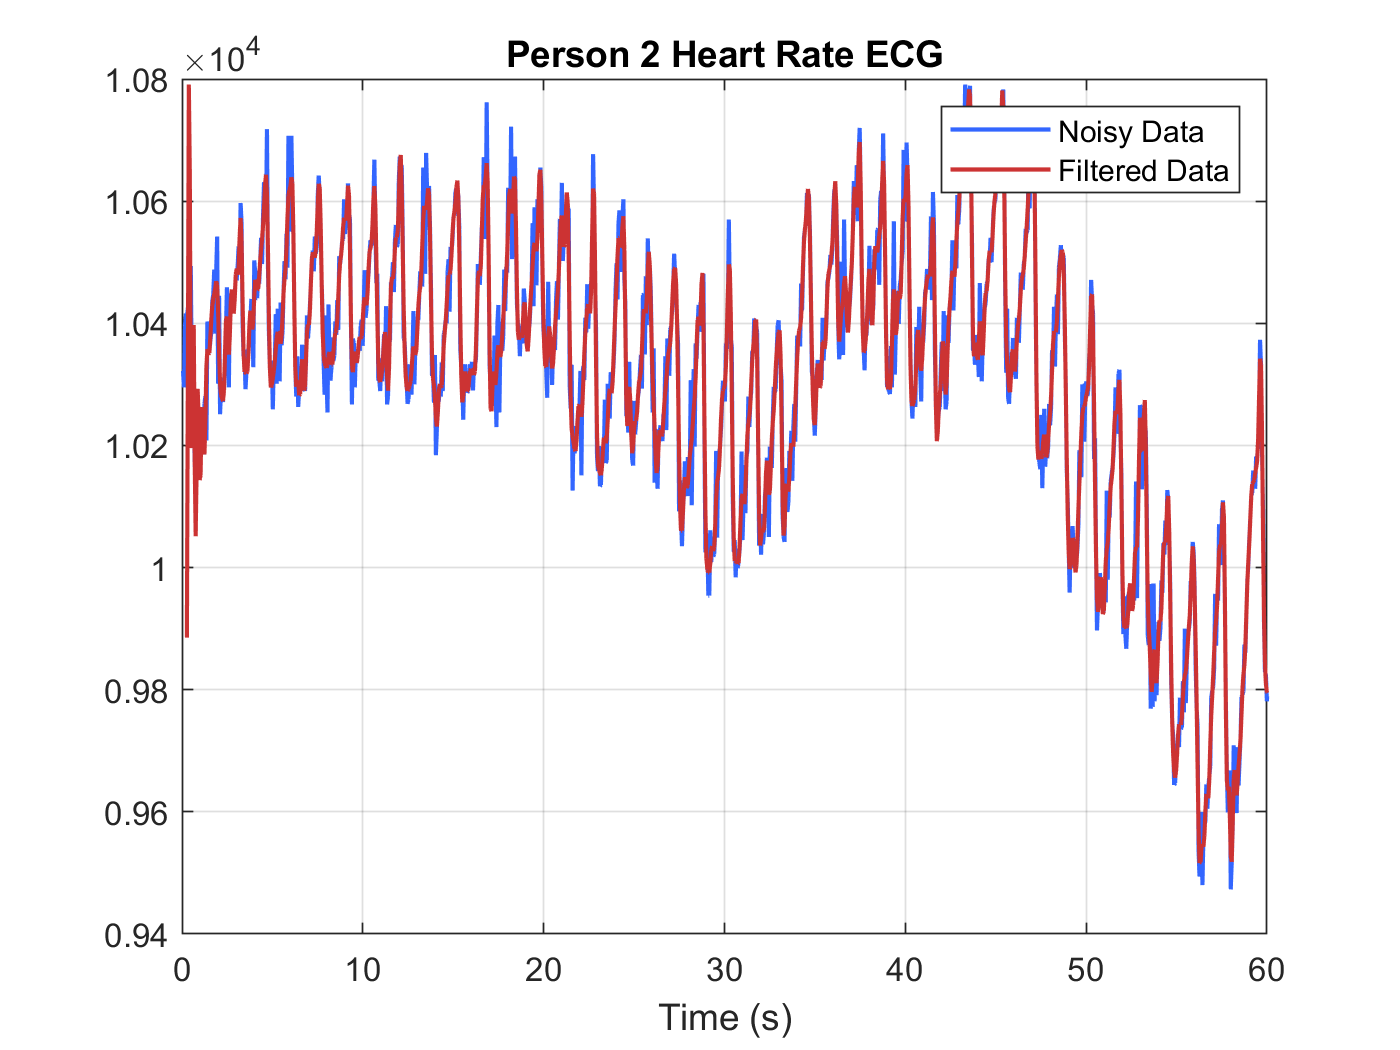

% --Isolate person 2 data
    figure3 = figure(3);
    plot(time,pulsePerson2,'Color',[0.2 0.4 1],'LineWidth',1.25);
        xlim([0 60])
        xlabel('Time (s)')
        title('Person 2 Heart Rate ECG')
        hold on

% --Filter ECG Signal
    filteredPulse2 = lowpass(pulsePerson2,0.4);
    filteredPulse2 = filteredPulse2(5:length(filteredPulse2)-2);
    filteredTime = time(5:length(time)-2);
    plot(filteredTime,filteredPulse2,'Color',[0.8 0.2 0.2],'LineWidth',1.25);
        legend('Noisy Data','Filtered Data')
        grid on

    Person 2 FFT Calculations and frequency spectrum plot.

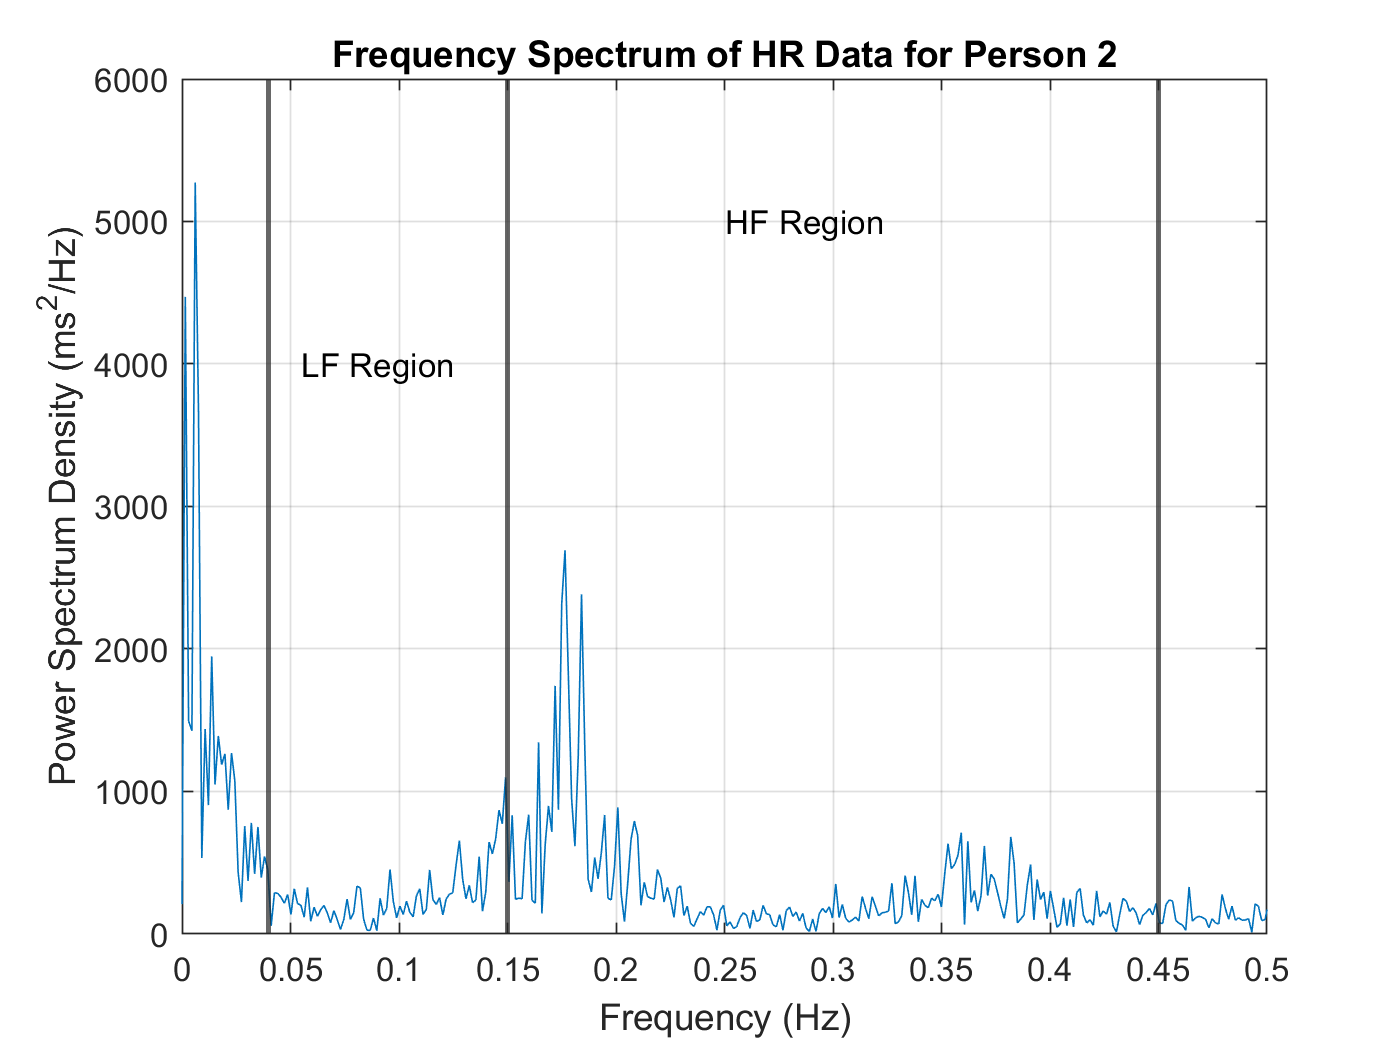

% --FFT of person 2 data
    signalLength = length(filteredPulse2);                      % Signal length
    
    powerPerson2 = fft(filteredPulse2);
    powerPerson2 = powerPerson2(4:(signalLength/2));
    PSD2 = (abs(powerPerson2))/(2*sample_frequency);            % Power spectral density of person 2 data
    
% --Calculating frequency
    frequency = linspace(0,2.5,length(PSD2));                   % Frequency Spectrum                 
    
% --Plotting FFT diagram
    figure();
    plot(frequency,PSD2)
        xlim([0 0.5])
        xlabel('Frequency (Hz)')
        title('Frequency Spectrum of HR Data for Person 2')
        ylabel('Power Spectrum Density (ms^2/Hz)')
        grid on
        
% --Indicate frequency regions
xline(0.15, 'LineWidth', 1.5)
    text(0.25,5000,'HF Region')
xline(0.45, 'LineWidth', 1.5)
xline(0.04, 'LineWidth', 1.5)
    text(0.055, 4000, 'LF Region')

    
% --Finding area under curve
sigma2 = trapz(PSD2);                 % Calculate the integral
fprintf('The area under the curve of the frequency spectrum is %3.3f',sigma2)

The area under the curve of the frequency spectrum is 205204.474

### Analysis

    HRV can be estimated by finding the area under the curve of the frequency spectrum graph that is created by taking the FFT of the data. From the generated plots above, person 1 has a lower area under the FFT curve so it could indicate that the person's HRV is lower than person 1 who's area under the frequency curve is higher. However, this analysis may not be fully trusted because of the data that is in the ULF zone that could affect the measurements. Based on the calculations I made person 2 has a higher chance of developing health issues because their HRV is lower than person 1. 